### Oppgave 2

First we define the Vektor field E 

syms Ex(x,y,z) Ey(x,y,z) Ez(x,y,z) x1 y1 l11(t) l12(t) l13(t)

Ex(x,y,z) = 6*x*y;
Ey(x,y,z) = 3*x^2 - 3*y^2;
Ez(x,y,z) = 0;

Plott the vector field for visbility

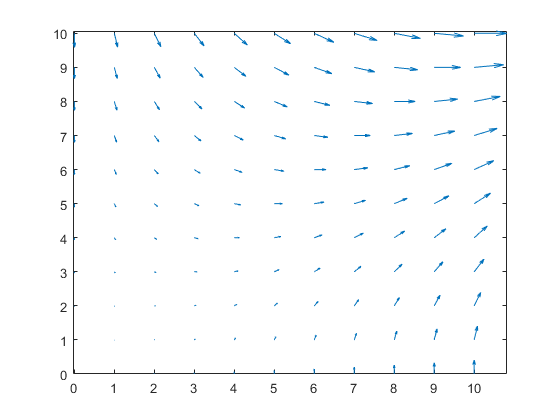

[xx,yy,zz] = meshgrid(0:1:10,0:1:10,0:1:10);
ex = 6.*xx.*yy;
ey = 3.*xx.^2 - 3.*yy.^2;
ez = 0.*xx;
quiver(xx,yy,ex,ey), axis tight

The line integral is calculated with this formualr

syms W r(s) F(r) 

W=int(F(r)*diff(r)*diff(s))

$$W(s) = \int F\left(r\left(s\right)\right)\,\frac{\partial }{\partial s}r\left(s\right)\mathrm{d}s$$

The parametric equation for straight line is:

(x0,y0,z0) to (x1,y1,z1) --> 

x = (1-t)*x0 + t*x1

y = (1-t0)*y0 + t*y1

z = (1-t)*z0 + t*z1

For the calculation t is set to beetween [0 1]

### C1

First the movement from origo to (x1,0,0)

l11(t) = x1*t;
l12(t) = 0;
l13(t) = 0;

l = [l11; l12; l13];
E = [Ex; Ey; Ez];

Er = E(l11(t), l12(t), l13(t));
dl = diff(l(t), t);

integrand = dot(Er,dl);

work1 = int(integrand, t, [0 1])

$$work1 = 0$$

### C2

Then from (x1,0,0) to (x1,y1,0)

syms l21(t) l22(t) l23(t)

l21(t) = (1-t)*x1 + x1*t;
l22(t) = y1*t;
l23(t) = 0;

l2 = [l21; l22; l23];

Er2 = E(l21(t), l22(t), l23(t));
dl2 = diff(l2(t), t);

integrand2 = dot(Er2, dl2);

work2 = int(integrand2, t, [0 1])

$$work2 = 3\,y_{1}\,{\bar{x_{1}}}^{2}-y_{1}\,{\bar{y_{1}}}^{2}$$

### C3

Then for the other way, from otigo to (0,y1,0)

syms l31(t) l32(t) l33(t)

l31(t) = 0;
l32(t) = y1*t;
l33(t) = 0;

l3 = [l31; l32; l33];

Er3 = E(l31(t), l32(t), l33(t));
dl3 = diff(l3(t), t);

integrand3 = dot(Er3, dl3);

dll = diff(l3(t),t);

work3 = int(integrand3, t, [0 1])

$$work3 = -y_{1}\,{\bar{y_{1}}}^{2}$$

### C4

From (0,y1,0) to (x1,y1,0)

syms l41(t) l42(t) l43(t)

l41(t) = x1*t;
l42(t) = (1-t)*y1 + t*y1;
l43(t) = 0;

l4 = [l41; l42; l43];

Er4 = E(l41(t), l42(t), l43(t));
dl4 = diff(l4(t), t);

integrand4 = dot(Er4, dl4);

work4 = int(integrand4, t, [0 1])

$$work4 = 3\,{\left|x_{1}\right|}^{2}\,\bar{y_{1}}$$

### C1+C2 and C3+C4

Add the found work for comparison

workWay1 = work1 + work2

$$workWay1 = 3\,y_{1}\,{\bar{x_{1}}}^{2}-y_{1}\,{\bar{y_{1}}}^{2}$$

workWay2 = work3 + work4

$$workWay2 = 3\,{\left|x_{1}\right|}^{2}\,\bar{y_{1}}-y_{1}\,{\bar{y_{1}}}^{2}$$


differance = workWay1 - workWay2

$$differance = 3\,y_{1}\,{\bar{x_{1}}}^{2}-3\,{\left|x_{1}\right|}^{2}\,\bar{y_{1}}$$


diffNum = subs(differance,{x1 y1},{1 -1})

$$diffNum = 0$$

The difference is not equal to zero because MATLAB tells s that one of the x1 have to be absolutt. Since the x value is squared this may be neglected anyway and the difference would be zero. As numericaly shown in the diff num for [-1 1]. It is check for multiple values. The E indeed represent a electrostatic field.

### C5

syms l15(t) l52(t) l53(t)

l51(t) = x1*t;
l52(t) = y1*t;
l53(t) = 0;

l5 = [l51; l52; l53];

Er5 = E(l51(t), l52(t), l53(t));
d15 = diff(l5(t), t);

integrand5 = dot(Er5, d15)

$$integrand5 = y_{1}\,\left(3\,{\bar{t}}^{2}\,{\bar{x_{1}}}^{2}-3\,{\bar{t}}^{2}\,{\bar{y_{1}}}^{2}\right)+6\,x_{1}\,{\bar{t}}^{2}\,\bar{x_{1}}\,\bar{y_{1}}$$


work5 = int(integrand5, t, [0 1])

$$work5 = \frac{y_{1}\,\left(3\,{\bar{x_{1}}}^{2}-3\,{\bar{y_{1}}}^{2}\right)}{3}+2\,x_{1}\,\bar{x_{1}}\,\bar{y_{1}}$$

syms Ed(x,y,z)

dx = diff(x);
dy = diff(y);

Ed(x,y,z) = 6*x*y*dx + (3*x^2 - 3*y^2)*dy == 0;

%ySolve(t) = dsolve(Ed, )

B)

c)